**Homework Assignment 1**  

Everyone will build your own version of a very basic image processing pipeline (without denoising and color transformsteps), to convert a RAW image into an image that can be displayed on a computer monitor or printed on paper.  

**1. Initials.**

 Load the image into Matlab.  

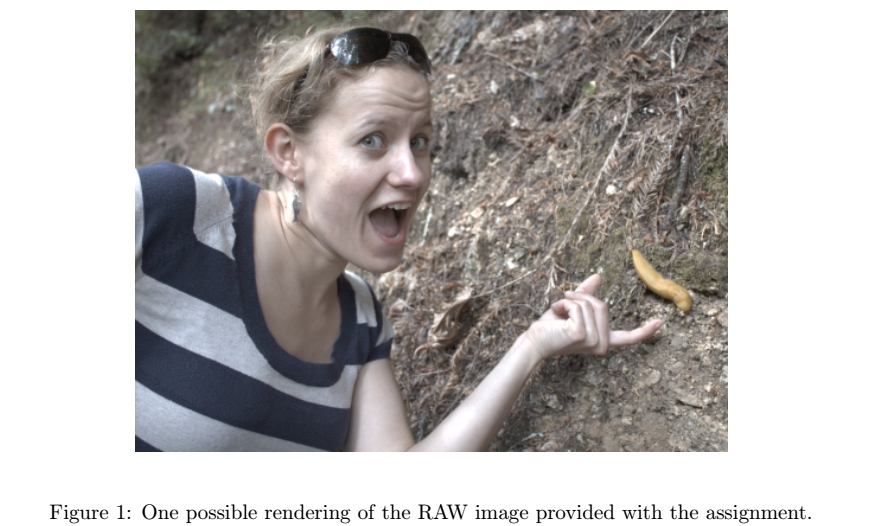

clc;
orgImg = imread('C:/Users/Amor/Desktop/assgn1/src/banana_slug.tiff')

orgImg = 2856×4290 uint16 矩阵
   2217   2391   2229   2456   2223   2481   2241   2474   2220   2448   2258   2521   2259   2483   2257   2505   2199   2463   2212   2432   2241   2468   2199   2501   2207   2449   2201   2466   2227   2471   2195   2439   2199   2424   2216   2390   2185   2358   2191   2326   2170   2337   2174   2299   2167   2315   2158   2305   2163   2251
   2407   2209   2467   2237   2440   2237   2501   2250   2428   2250   2482   2236   2486   2285   2545   2272   2447   2285   2462   2249   2483   2287   2472   2274   2494   2248   2483   2217   2506   2248   2444   2223   2452   2197   2395   2196   2332   2183   2346   2167   2306   2149   2286   2160   2306   2142   2311   2188   2285   2158
   2239   2437   2244   2481   2235   2438   2240   2439   2262   2481   2239   2491   2264   2485   2242   2493   2221   2477   2242   2489   2247   2527   2218   2509   2230   2439   2219   2467   2252   2471   2236   2490   2216   2340   2193   2389   2197   2348   

display the size of orgImg

% displaly the height and width 
size(orgImg)

ans =         2856        4290


% convert the image into a double-precision array
doubleOrgImg = im2double(orgImg)

doubleOrgImg =     0.0338    0.0365    0.0340    0.0375    0.0339    0.0379    0.0342    0.0378    0.0339    0.0374    0.0345    0.0385    0.0345    0.0379    0.0344    0.0382    0.0336    0.0376    0.0338    0.0371    0.0342    0.0377    0.0336    0.0382    0.0337    0.0374    0.0336    0.0376    0.0340    0.0377    0.0335    0.0372    0.0336    0.0370    0.0338    0.0365    0.0333    0.0360    0.0334    0.0355    0.0331    0.0357    0.0332    0.0351    0.0331    0.0353    0.0329    0.0352    0.0330    0.0343
    0.0367    0.0337    0.0376    0.0341    0.0372    0.0341    0.0382    0.0343    0.0370    0.0343    0.0379    0.0341    0.0379    0.0349    0.0388    0.0347    0.0373    0.0349    0.0376    0.0343    0.0379    0.0349    0.0377    0.0347    0.0381    0.0343    0.0379    0.0338    0.0382    0.0343    0.0373    0.0339    0.0374    0.0335    0.0365    0.0335    0.0356    0.0333    0.0358    0.0331    0.0352    0.0328    0.0349    0.0330    0.0352    0.0327    0.0353    0.0334    

**2. Linearization.**  

% define the black and overexposed threshold.
black = 2047;
overexposed = 15000;
%change the value
linearImg=orgImg;
linearImg(linearImg<black)=black;
linearImg(linearImg>overexposed)=overexposed;
linearImg = linearImg - black

linearImg = 2856×4290 uint16 矩阵
   170   344   182   409   176   434   194   427   173   401   211   474   212   436   210   458   152   416   165   385   194   421   152   454   160   402   154   419   180   424   148   392   152   377   169   343   138   311   144   279   123   290   127   252   120   268   111   258   116   204
   360   162   420   190   393   190   454   203   381   203   435   189   439   238   498   225   400   238   415   202   436   240   425   227   447   201   436   170   459   201   397   176   405   150   348   149   285   136   299   120   259   102   239   113   259    95   264   141   238   111
   192   390   197   434   188   391   193   392   215   434   192   444   217   438   195   446   174   430   195   442   200   480   171   462   183   392   172   420   205   424   189   443   169   293   146   342   150   301   153   291   118   272   128   243   127   237   114   227    94   237
   362   176   406   163   379   150   392   183   382   189   43

%normlization
normImg = linearImg* (1./(overexposed-black));
normImg = double(normImg);

**3. Identifying the correct Bayer pattern**

Think of a way for identifying which version of the Bayer patterns applies to our image file, and report which version you identified.   

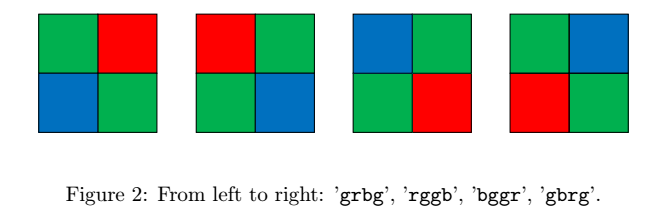

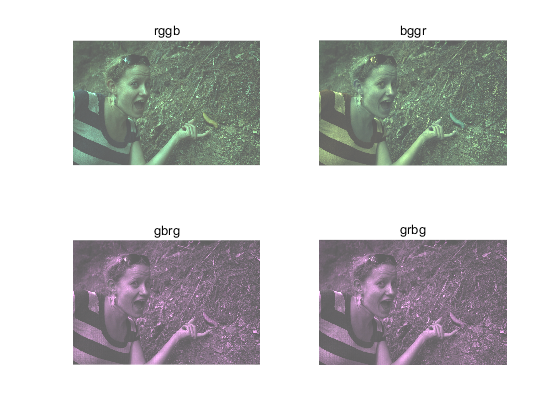

% using the demosaic function in matlab
Img_rggb = demosaic(orgImg,'rggb');
Img_bggr = demosaic(orgImg,'bggr');
Img_gbrg = demosaic(orgImg,'gbrg');
Img_grbg = demosaic(orgImg,'grbg');
%display the image with different bayer pattern
figure;
subplot(2,2,1);
imshow(Img_rggb*12);
title('rggb');
subplot(2,2,2);
imshow(Img_bggr*12);
title('bggr');
subplot(2,2,3);
imshow(Img_gbrg*12);
title('gbrg');
subplot(2,2,4);
imshow(Img_grbg*12);
title('grbg');

**4. White balancing**  

    algorithm 1 :  using mean of three channels .

% get the H and W 
[orgH, orgW] = size(linearImg);
% get the data of R G B 
R = linearImg(1:2:end,1:2:end);
B = linearImg(2:2:end,2:2:end);
G1 = linearImg(1:2:end,2:2:end);
G2 = linearImg(2:2:end,1:2:end);
G = [G1;G2];
% befor white balance. compute the mean of R G B channels
meanR = mean(mean(R))

meanR = 411.2180

meanB = mean(mean(B))

meanB = 431.1640

meanG = mean(mean(G))

meanG = 752.6595

meanG/meanR

ans = 1.8303

meanG/meanB

ans = 1.7456

wbImg = linearImg;
% white balancing
% do R channel data
for i = 1:2:orgH
    for j = 1:2:orgW
        wbImg(i,j)=wbImg(i,j)*(meanG/meanR);
    end
    
end
% do B channel data
for i = 2:2:orgH
    for j= 2:2:orgW
        wbImg(i,j)=wbImg(i,j)*(meanG/meanB);
    end
end

% the mean of R G B channel and ratio after white balance 
wbR = wbImg(1:2:end,1:2:end);
wbB = wbImg(2:2:end,2:2:end);
wbwG1 = wbImg(1:2:end,2:2:end);
wbG2 = wbImg(2:2:end,1:2:end);
wbG = [G1;G2];
% compute the mean of R G B channels
meanR = mean(mean(wbR))

meanR = 752.6605

meanB = mean(mean(wbB))

meanB = 752.6589

meanG = mean(mean(wbG))

meanG = 752.6595

meanG/meanR

ans = 1.0000

meanG/meanB

ans = 1.0000

figure;
imshow(wbImg*12);

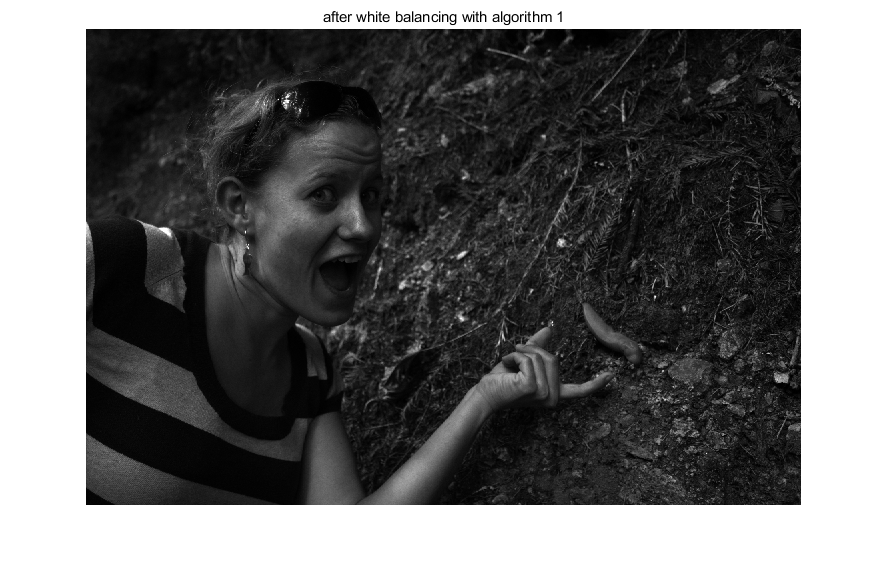

title('after white balancing with algorithm 1');

algorithm 2 : using max value of three channels 

% get the H and W 
[orgH, orgW] = size(linearImg);
% get the data of R G B 
R = linearImg(1:2:end,1:2:end);
B = linearImg(2:2:end,2:2:end);
G1 = linearImg(1:2:end,2:2:end);
G2 = linearImg(2:2:end,1:2:end);
G = [G1;G2];
% befor white balance. compute the max value of R G B channels
maxR = max(max(R))

maxR = uint16
4912

maxB = max(max(B))

maxB = uint16
8489

maxG = max(max(G))

maxG = uint16
12953

maxG/maxR

ans = uint16
3

maxG/maxB

ans = uint16
2

wbImg2 = linearImg;
% white balancing
% do R channel data
for i = 1:2:orgH
    for j = 1:2:orgW
        wbImg2(i,j)=wbImg2(i,j)*(maxG/maxR);
    end
end
% do B channel data
for i = 2:2:orgH
    for j= 2:2:orgW
        wbImg2(i,j)=wbImg2(i,j)*(maxG/maxB);
    end
end

% the mean of R G B channel and ratio after white balance 
wbR = wbImg2(1:2:end,1:2:end);
wbB = wbImg2(2:2:end,2:2:end);
wbwG1 = wbImg2(1:2:end,2:2:end);
wbG2 = wbImg2(2:2:end,1:2:end);
wbG = [G1;G2];
% compute the max value of R G B channels
maxR = max(max(wbR))

maxR = uint16
14736

maxB = max(max(wbB))

maxB = uint16
16978

maxG = max(mean(wbG))

maxG = 1.0459e+03

maxG/maxR

ans = uint16
0

maxG/maxB

ans = uint16
0

figure;
imshow(wbImg2*12);

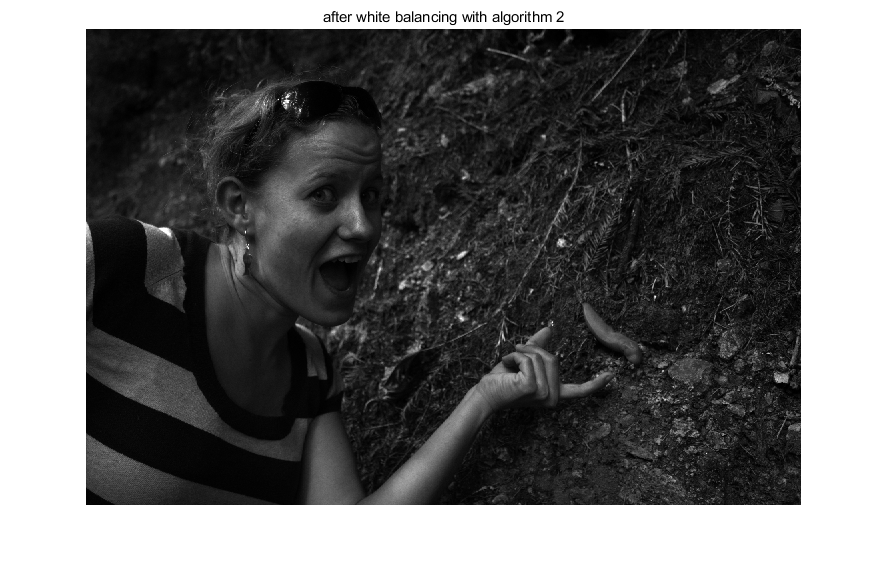

title('after white balancing with algorithm 2');

**5. Demosaicing**  

% demosaicing
wbImg = double(wbImg)/255/255; % using white balance algo 1
%wbImg = double(wbImg2)/255/255; % using white balance algo 2
R = wbImg(1:2:end,1:2:end);
B = wbImg(2:2:end,2:2:end);
G1 = wbImg(1:2:end,2:2:end);
G2 = wbImg(2:2:end,1:2:end);
x=1:2:orgW;
y=1:2:orgH;
[x,y]=meshgrid(x,y);
xq=1:orgW;
yq=1:orgH;
[xq,yq]=meshgrid(xq,yq);
demoImgR = interp2(x,y,R,xq,yq)

demoImgR =     0.0078    0.0081    0.0084    0.0083    0.0081    0.0085    0.0090    0.0085    0.0080    0.0089    0.0097    0.0098    0.0098    0.0097    0.0097    0.0084    0.0070    0.0073    0.0076    0.0083    0.0090    0.0080    0.0070    0.0072    0.0074    0.0072    0.0071    0.0077    0.0083    0.0076    0.0068    0.0069    0.0070    0.0074    0.0078    0.0071    0.0064    0.0065    0.0066    0.0062    0.0057    0.0058    0.0059    0.0057    0.0055    0.0053    0.0051    0.0052    0.0054    0.0046
    0.0084    0.0085    0.0087    0.0086    0.0084    0.0087    0.0089    0.0089    0.0090    0.0091    0.0093    0.0096    0.0099    0.0096    0.0093    0.0084    0.0075    0.0079    0.0083    0.0087    0.0091    0.0083    0.0075    0.0077    0.0079    0.0077    0.0075    0.0082    0.0089    0.0083    0.0078    0.0076    0.0074    0.0073    0.0073    0.0070    0.0066    0.0067    0.0069    0.0062    0.0056    0.0057    0.0059    0.0058    0.0057    0.0054    0.0052    0.0050    0.00

[bh,bw]=size(B);
B1 = zeros(bh+1,bw+1);
B1(2:bh+1,2:bw+1)=B;
x=1:2:orgW+1;
y=1:2:orgH+1;
[x,y]=meshgrid(x,y);
xq=2:orgW+1;
yq=2:orgH+1;
[xq,yq]=meshgrid(xq,yq);
demoImgB = interp2(x,y,B1,xq,yq)

demoImgB =     0.0012    0.0025    0.0027    0.0029    0.0029    0.0029    0.0030    0.0031    0.0031    0.0031    0.0030    0.0029    0.0033    0.0037    0.0036    0.0035    0.0036    0.0037    0.0034    0.0031    0.0034    0.0037    0.0036    0.0035    0.0033    0.0031    0.0029    0.0026    0.0029    0.0031    0.0029    0.0027    0.0025    0.0023    0.0023    0.0023    0.0022    0.0021    0.0020    0.0018    0.0017    0.0016    0.0017    0.0017    0.0016    0.0015    0.0018    0.0022    0.0019    0.0017
    0.0025    0.0050    0.0054    0.0058    0.0058    0.0058    0.0060    0.0062    0.0062    0.0062    0.0060    0.0058    0.0066    0.0073    0.0071    0.0069    0.0071    0.0073    0.0068    0.0062    0.0068    0.0074    0.0072    0.0070    0.0066    0.0062    0.0057    0.0052    0.0057    0.0062    0.0058    0.0054    0.0050    0.0046    0.0046    0.0046    0.0044    0.0042    0.0039    0.0037    0.0034    0.0031    0.0033    0.0035    0.0032    0.0029    0.0036    0.0043    0.00

% interp G1 channel
[bh,bw]=size(G1);
G11 = zeros(bh+1,bw+1);
G11(2:bh+1,2:bw+1)=G1;
x=1:2:orgW+1;
y=1:2:orgH+1;
[x,y]=meshgrid(x,y);
xq=2:orgW+1;
yq=2:orgH+1;
[xq,yq]=meshgrid(xq,yq);
demoImgG1 = interp2(x,y,G11,xq,yq)

demoImgG1 =     0.0013    0.0026    0.0029    0.0031    0.0032    0.0033    0.0033    0.0033    0.0032    0.0031    0.0034    0.0036    0.0035    0.0034    0.0034    0.0035    0.0034    0.0032    0.0031    0.0030    0.0031    0.0032    0.0034    0.0035    0.0033    0.0031    0.0032    0.0032    0.0032    0.0033    0.0031    0.0030    0.0030    0.0029    0.0028    0.0026    0.0025    0.0024    0.0023    0.0021    0.0022    0.0022    0.0021    0.0019    0.0020    0.0021    0.0020    0.0020    0.0018    0.0016
    0.0026    0.0053    0.0058    0.0063    0.0065    0.0067    0.0066    0.0066    0.0064    0.0062    0.0067    0.0073    0.0070    0.0067    0.0069    0.0070    0.0067    0.0064    0.0062    0.0059    0.0062    0.0065    0.0067    0.0070    0.0066    0.0062    0.0063    0.0064    0.0065    0.0065    0.0063    0.0060    0.0059    0.0058    0.0055    0.0053    0.0050    0.0048    0.0045    0.0043    0.0044    0.0045    0.0042    0.0039    0.0040    0.0041    0.0040    0.0040    0.0

% interp G2 channel
[bh,bw]=size(G2);
G21 = zeros(bh+1,bw+1);
G21(2:bh+1,2:bw+1)=G2;
x=1:2:orgW+1;
y=1:2:orgH+1;
[x,y]=meshgrid(x,y);
xq=2:orgW+1;
yq=2:orgH+1;
[xq,yq]=meshgrid(xq,yq);
demoImgG2 = interp2(x,y,G21,xq,yq)

demoImgG2 =     0.0014    0.0028    0.0030    0.0032    0.0031    0.0030    0.0033    0.0035    0.0032    0.0029    0.0031    0.0033    0.0034    0.0034    0.0036    0.0038    0.0035    0.0031    0.0031    0.0032    0.0033    0.0034    0.0033    0.0033    0.0034    0.0034    0.0034    0.0034    0.0034    0.0035    0.0033    0.0031    0.0031    0.0031    0.0029    0.0027    0.0024    0.0022    0.0022    0.0023    0.0021    0.0020    0.0019    0.0018    0.0019    0.0020    0.0020    0.0020    0.0019    0.0018
    0.0028    0.0055    0.0060    0.0065    0.0063    0.0060    0.0065    0.0070    0.0064    0.0059    0.0063    0.0067    0.0067    0.0068    0.0072    0.0077    0.0069    0.0062    0.0063    0.0064    0.0065    0.0067    0.0066    0.0065    0.0067    0.0069    0.0068    0.0067    0.0069    0.0071    0.0066    0.0061    0.0062    0.0062    0.0058    0.0054    0.0049    0.0044    0.0045    0.0046    0.0043    0.0040    0.0038    0.0037    0.0038    0.0040    0.0040    0.0041    0.0

% merge the G1 and G2
demoImgG = (demoImgG1+demoImgG2)*0.5;
rgbImg = cat(3,demoImgR,demoImgG,demoImgB);
figure;
imshow(rgbImg);

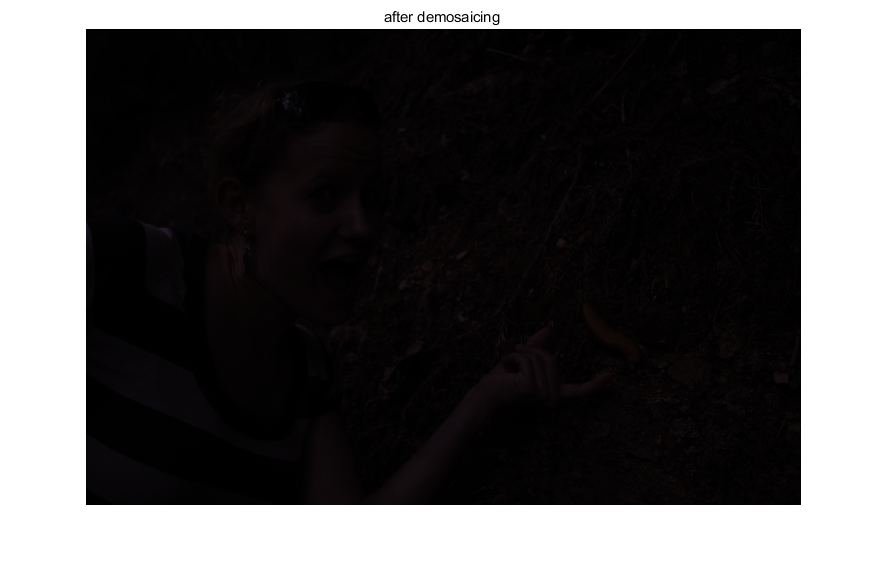

title('after demosaicing ');

**6.1 Brightness adjustment and gamma correction**

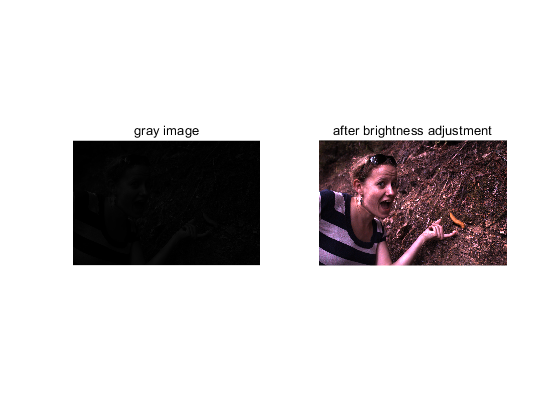

% convert to gray image
grayImg = rgb2gray(rgbImg);
maxValue = max(max(grayImg));
rgbImg = rgbImg * (1/maxValue)*3;
figure;
subplot(1,2,1);
imshow(grayImg);
title('gray image');
subplot(1,2,2);
imshow(rgbImg);
title('after brightness adjustment');

**6.2 gamma correction**


$$C_{\mathrm{non}-\mathrm{linear}} =\lbrace_{\left(1+0\ldotp 055\right)*C_{\mathrm{linear}}^{\frac{1}{2\ldotp 4}} -0\ldotp 055,\;\;C_{\mathrm{linear}} \ge 0\ldotp 0031308}^{12\ldotp 92\cdot C_{\mathrm{linear}} ,\;\;{\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;C}_{\mathrm{linear}} \le 0\ldotp 0031308}$$
  

% build the loop up table
lut = 0:255;
norLut = lut./255;
% compute the gama correction para
for i=1:256
    if(norLut(i)<0.0031308)
        norLut(i)=norLut(i)*12.92;
    else
        norLut(i)=(1+0.055)*norLut(i)^(1/2.4)-0.055;
    end
end
% mapping the norLut to rgbImg
intRgbImg = im2uint8(rgbImg);
intRgbImg = intRgbImg +1;
intNorLut = norLut*255;
gamaImg = intNorLut(intRgbImg);
gamaImg = gamaImg /255;
figure;
imshow(gamaImg);

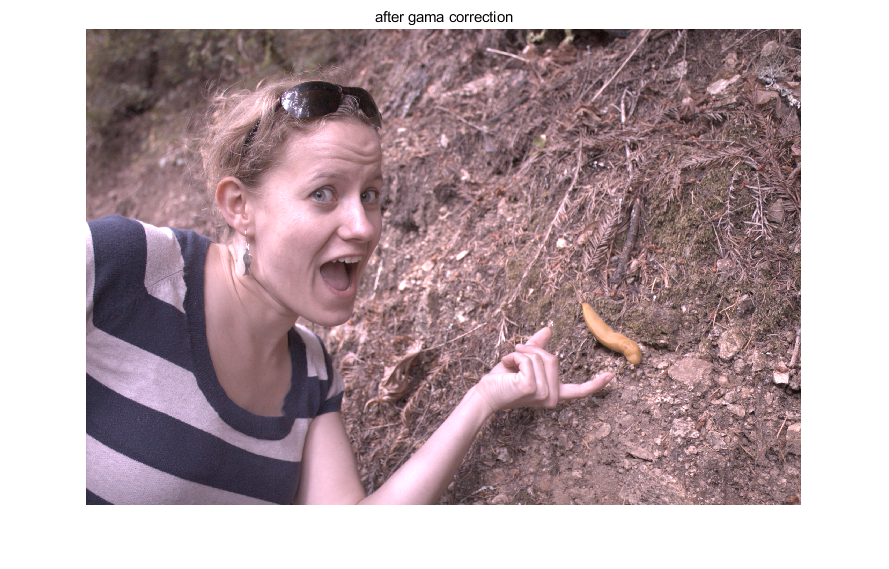

title('after gama correction');

**7. Compression**  

Use the imwrite command to store the image in .PNG format (no compression), and also in .JPEG format with quality setting 95.   

ratio = bytes_after_compression / bytes_before_compression

difference between .PNG format and .JPEG format:

gamaCorrect.png = 16.2 M

gamaCorrect.jpg  = 3.17 M

% PNG format
imwrite(gamaImg,'.\gamaCorrect.png');
% JPG format with quality 95
%imwrite(gamaImg,'.\gamaCorrect.jpg','Quality',95);